### **Esame 2018**

Esercizio 1

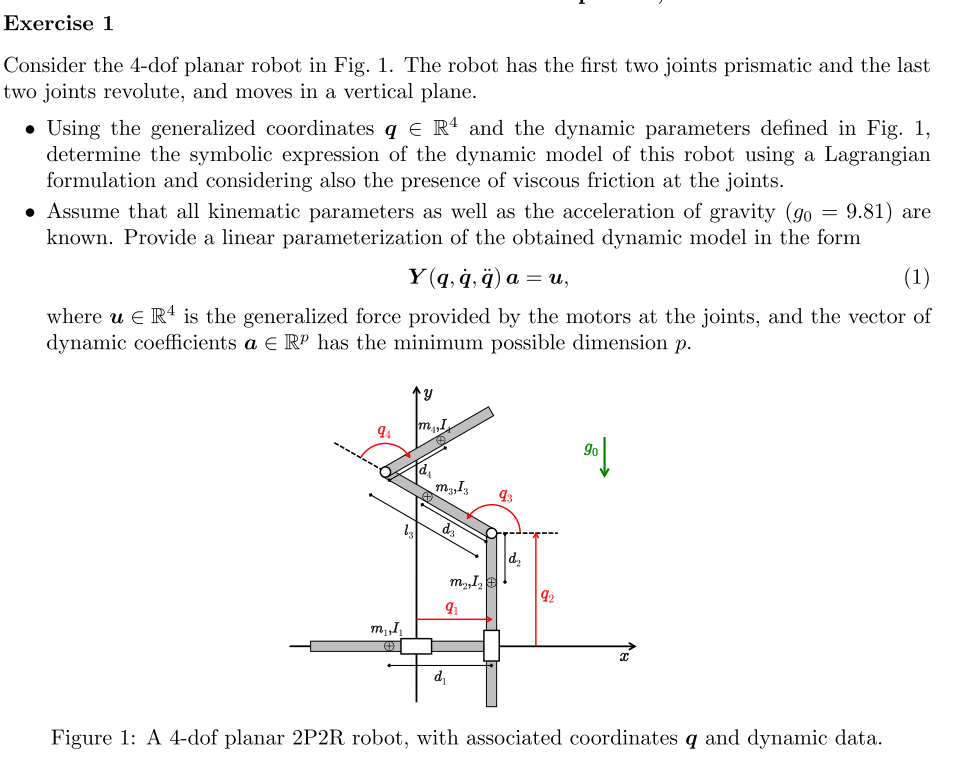

clc 
clear all
close all
syms g0 q_dot_1 q_dot_2 q_dot_3 q_dot_4 d1 d2 d3 d4 I3_zz I4_zz l1 l2 l3 m1 m2 m3 m4 q1 q2 q3 q4 q_dot_dot_1 q_dot_dot_2 q_dot_dot_3 q_dot_dot_4 real
syms a1 a2 a3 a4 a5 a6 real

q = [q1 q2 q3 q4]';
q_dot = [q_dot_1 q_dot_2 q_dot_3 q_dot_4]';
q_dot_dot = [q_dot_dot_1 q_dot_dot_2 q_dot_dot_3 q_dot_dot_4]';

pc1 = [q1-d1 0 0]';
vc1 = [q_dot_1  0    0]';
pc2 = [q1 q2-d2 0]';
vc2 = [q_dot_1  q_dot_2     0]';
pc3 = [q1+d3*cos(q3)    q2+d3*sin(q3)   0]';
vc3 = [q_dot_1-d3*sin(q3)*q_dot_3   q_dot_2+d3*cos(q3)*q_dot_3  0]';
pc4 = [q1+l3*cos(q3)+d4*cos(q3+q4)  q2+l3*sin(q3)+d4*sin(q3+q4) 0]';
vc4 = [q_dot_1-l3*sin(q3)*q_dot_3-d4*sin(q3+q4)*(q_dot_3+q_dot_4)   q_dot_2+l3*cos(q3)*q_dot_3+d4*cos(q3+q4)*(q_dot_3+q_dot_4)  0]';

omega3 = [0   0   q_dot_3]';
omega4 = [0   0   q_dot_3+q_dot_4]';

T1  = 1/2*m1*vc1'*vc1;
T2  = 1/2*m2*vc2'*vc2;
T3 = 1/2*m3*vc3'*vc3 + 1/2*omega3'*omega3*I3_zz;
T4 = 1/2*m4*vc4'*vc4 + 1/2*omega4'*omega4*I4_zz;

T = T1+T2+T3+T4;

g=[0 -g0 0]';

U1 = -m1*g'*pc1;
U2 = -m2*g'*pc2;
U3 = -m3*g'*pc3;
U4 = -m4*g'*pc4;

U = simplify(U1+U2+U3+U4);

g_fun=jacobian(U, q)'

$$g\_fun = \left(\begin{array}{c} 0\\ g_{0}\,m_{2}+g_{0}\,m_{3}+g_{0}\,m_{4}\\ g_{0}\,m_{4}\,\left(d_{4}\,\cos\left(q_{3}+q_{4}\right)+l_{3}\,\cos\left(q_{3}\right)\right)+d_{3}\,g_{0}\,m_{3}\,\cos\left(q_{3}\right)\\ d_{4}\,g_{0}\,m_{4}\,\cos\left(q_{3}+q_{4}\right) \end{array}\right)$$


g_fun=[0 ;
        a2*g0 ;
        a5*g0*cos(q3+q4)+g0*cos(q3)*a6;
        g0*a5*cos(q3+q4)];


M=fai_sparire_gli_zeri(simplify( hessian(T,q_dot) ))

$$M = \begin{array}{l} \left(\begin{array}{cccc} m_{1}+m_{2}+m_{3}+m_{4} & 0 & \sigma_{1} & -1.0\,d_{4}\,m_{4}\,\sin\left(q_{3}+q_{4}\right)\\ 0 & m_{2}+m_{3}+m_{4} & \sigma_{3} & \sigma_{4}\\ \sigma_{1} & \sigma_{3} & m_{3}\,{d_{3}}^{2}+m_{4}\,{d_{4}}^{2}+2.0\,m_{4}\,\cos\left(q_{4}\right)\,d_{4}\,l_{3}+m_{4}\,{l_{3}}^{2}+I_{3,\mathrm{zz}}+I_{4,\mathrm{zz}} & \sigma_{2}\\ -1.0\,d_{4}\,m_{4}\,\sin\left(q_{3}+q_{4}\right) & \sigma_{4} & \sigma_{2} & m_{4}\,{d_{4}}^{2}+I_{4,\mathrm{zz}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-d_{3}\,m_{3}\,\sin\left(q_{3}\right)-l_{3}\,m_{4}\,\sin\left(q_{3}\right)-d_{4}\,m_{4}\,\sin\left(q_{3}+q_{4}\right)\\ \sigma_{2}=m_{4}\,{d_{4}}^{2}+l_{3}\,m_{4}\,\cos\left(q_{4}\right)\,d_{4}+I_{4,\mathrm{zz}}\\ \sigma_{3}=d_{3}\,m_{3}\,\cos\left(q_{3}\right)+l_{3}\,m_{4}\,\cos\left(q_{3}\right)+\sigma_{4}\\ \sigma_{4}=d_{4}\,m_{4}\,\cos\left(q_{3}+q_{4}\right) \end{array}$$

collect(M, [sin(q3+q4) cos(q3+q4) sin(q3) cos(q3) cos(q4) sin(q4)])

$$ans = \begin{array}{l} \left(\begin{array}{cccc} m_{1}+m_{2}+m_{3}+m_{4} & 0 & \sigma_{1} & \sigma_{3}\\ 0 & m_{2}+m_{3}+m_{4} & \sigma_{4} & \sigma_{5}\\ \sigma_{1} & \sigma_{4} & \left(2.0\,d_{4}\,l_{3}\,m_{4}\right)\,\cos\left(q_{4}\right)+m_{3}\,{d_{3}}^{2}+m_{4}\,{d_{4}}^{2}+m_{4}\,{l_{3}}^{2}+I_{3,\mathrm{zz}}+I_{4,\mathrm{zz}} & \sigma_{2}\\ \sigma_{3} & \sigma_{5} & \sigma_{2} & m_{4}\,{d_{4}}^{2}+I_{4,\mathrm{zz}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(-d_{4}\,m_{4}\right)\,\sin\left(q_{3}+q_{4}\right)+\left(-d_{3}\,m_{3}-l_{3}\,m_{4}\right)\,\sin\left(q_{3}\right)\\ \sigma_{2}=\left(d_{4}\,l_{3}\,m_{4}\right)\,\cos\left(q_{4}\right)+m_{4}\,{d_{4}}^{2}+I_{4,\mathrm{zz}}\\ \sigma_{3}=\left(-1.0\,d_{4}\,m_{4}\right)\,\sin\left(q_{3}+q_{4}\right)\\ \sigma_{4}=\sigma_{5}+\left(d_{3}\,m_{3}+l_{3}\,m_{4}\right)\,\cos\left(q_{3}\right)\\ \sigma_{5}=\left(d_{4}\,m_{4}\right)\,\cos\left(q_{3}+q_{4}\right) \end{array}$$



M=[ a1                          0                              -a5*sin(q3+q4)-a6*sin(q3)       -a5*sin(q3+q4);
    0                           a2                              a5*cos(q3+q4)+a6*cos(q3)        a5*cos(q3+q4);
   -a5*sin(q3+q4)-a6*sin(q3)    a5*cos(q3+q4)+a6*cos(q3)        2*l3*a5*cos(q4)+a3              l3*a5*cos(q4)+a4;
   -a5*sin(q3+q4)               a5*cos(q3+q4)                   l3*a5*cos(q4)+a4                a4]

$$M = \begin{array}{l} \left(\begin{array}{cccc} a_{1} & 0 & \sigma_{1} & -a_{5}\,\sin\left(q_{3}+q_{4}\right)\\ 0 & a_{2} & \sigma_{2} & \sigma_{3}\\ \sigma_{1} & \sigma_{2} & a_{3}+2\,a_{5}\,l_{3}\,\cos\left(q_{4}\right) & a_{4}+a_{5}\,l_{3}\,\cos\left(q_{4}\right)\\ -a_{5}\,\sin\left(q_{3}+q_{4}\right) & \sigma_{3} & a_{4}+a_{5}\,l_{3}\,\cos\left(q_{4}\right) & a_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-a_{5}\,\sin\left(q_{3}+q_{4}\right)-a_{6}\,\sin\left(q_{3}\right)\\ \sigma_{2}=\sigma_{3}+a_{6}\,\cos\left(q_{3}\right)\\ \sigma_{3}=a_{5}\,\cos\left(q_{3}+q_{4}\right) \end{array}$$

M*q_dot_dot

$$ans = \begin{array}{l} \left(\begin{array}{c} a_{1}\,{\dot{\dot{q}}}_{1}-{\dot{\dot{q}}}_{3}\,\sigma_{1}-a_{5}\,{\dot{\dot{q}}}_{4}\,\sin\left(q_{3}+q_{4}\right)\\ {\dot{\dot{q}}}_{3}\,\sigma_{2}+a_{2}\,{\dot{\dot{q}}}_{2}+a_{5}\,{\dot{\dot{q}}}_{4}\,\cos\left(q_{3}+q_{4}\right)\\ {\dot{\dot{q}}}_{2}\,\sigma_{2}-{\dot{\dot{q}}}_{1}\,\sigma_{1}+{\dot{\dot{q}}}_{3}\,\left(a_{3}+2\,a_{5}\,l_{3}\,\cos\left(q_{4}\right)\right)+{\dot{\dot{q}}}_{4}\,\sigma_{3}\\ a_{4}\,{\dot{\dot{q}}}_{4}+{\dot{\dot{q}}}_{3}\,\sigma_{3}+a_{5}\,{\dot{\dot{q}}}_{2}\,\cos\left(q_{3}+q_{4}\right)-a_{5}\,{\dot{\dot{q}}}_{1}\,\sin\left(q_{3}+q_{4}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{5}\,\sin\left(q_{3}+q_{4}\right)+a_{6}\,\sin\left(q_{3}\right)\\ \sigma_{2}=a_{5}\,\cos\left(q_{3}+q_{4}\right)+a_{6}\,\cos\left(q_{3}\right)\\ \sigma_{3}=a_{4}+a_{5}\,l_{3}\,\cos\left(q_{4}\right) \end{array}$$

%a1=m1+m2+m3+m4;
%a2=m2+m3+m4;
% a3=d4*m4;
% a4=m3*d3^2 + m4*d4^2 + m4*l3^2 + I3_zz + I4_zz;
% a5=m4*d4^2 + I4_zz;
% a6=  d3*m3 +l3*m4;
a=[a1 a2 a3 a4 a5 a6]';
%Y=simplify(jacobian(M, a))




%Calcolo simboli di christoffel
S=[];
c_i=[]*q(1);
for i=1:length(q_dot)
    M_i=M(:,i);
    Ci=simplify(1/2*(jacobian(M_i, q)+jacobian(M_i, q)'-diff(M, q(i)) ));
    Si=q_dot'*Ci;
    S=[S; Si];
    c_i=[c_i; q_dot'*Ci*q_dot]; 
end


syms a7 a8 a9 a10 real
F_v=[a7*q_dot_1 a8*q_dot_2 a9*q_dot_3 a10*q_dot_4]';
a=[a1 a2 a3 a4 a5 a6 a7 a8 a9 a10]';
%soluzione completa
u= fai_sparire_gli_zeri(simplify(M*q_dot_dot+c_i+g_fun))+F_v;
jacobian(u, a)

$$ans = \begin{array}{l} \left(\begin{array}{cccccccccc} {\dot{\dot{q}}}_{1} & 0 & 0 & 0 & -1.0\,\cos\left(q_{3}+q_{4}\right)\,{{\dot{q}}_{3}}^{2}-2.0\,\cos\left(q_{3}+q_{4}\right)\,{\dot{q}}_{3}\,{\dot{q}}_{4}-1.0\,\cos\left(q_{3}+q_{4}\right)\,{{\dot{q}}_{4}}^{2}-1.0\,{\dot{\dot{q}}}_{3}\,\sin\left(q_{3}+q_{4}\right)-1.0\,{\dot{\dot{q}}}_{4}\,\sin\left(q_{3}+q_{4}\right) & -1.0\,\cos\left(q_{3}\right)\,{{\dot{q}}_{3}}^{2}-1.0\,{\dot{\dot{q}}}_{3}\,\sin\left(q_{3}\right) & {\dot{q}}_{1} & 0 & 0 & 0\\ 0 & g_{0}+{\dot{\dot{q}}}_{2} & 0 & 0 & -1.0\,\sin\left(q_{3}+q_{4}\right)\,{{\dot{q}}_{3}}^{2}-2.0\,\sin\left(q_{3}+q_{4}\right)\,{\dot{q}}_{3}\,{\dot{q}}_{4}-1.0\,\sin\left(q_{3}+q_{4}\right)\,{{\dot{q}}_{4}}^{2}+{\dot{\dot{q}}}_{3}\,\cos\left(q_{3}+q_{4}\right)+{\dot{\dot{q}}}_{4}\,\cos\left(q_{3}+q_{4}\right) & {\dot{\dot{q}}}_{3}\,\cos\left(q_{3}\right)-1.0\,{{\dot{q}}_{3}}^{2}\,\sin\left(q_{3}\right) & 0 & {\dot{q}}_{2} & 0 & 0\\ 0 & 0 & {\dot{\dot{q}}}_{3} & {\dot{\dot{q}}}_{4} & -1.0\,l_{3}\,\sin\left(q_{4}\right)\,{{\dot{q}}_{4}}^{2}-2.0\,l_{3}\,{\dot{q}}_{3}\,\sin\left(q_{4}\right)\,{\dot{q}}_{4}+\sigma_{3}+\sigma_{2}-\sigma_{1}+2.0\,l_{3}\,{\dot{\dot{q}}}_{3}\,\cos\left(q_{4}\right)+l_{3}\,{\dot{\dot{q}}}_{4}\,\cos\left(q_{4}\right) & g_{0}\,\cos\left(q_{3}\right)+{\dot{\dot{q}}}_{2}\,\cos\left(q_{3}\right)-1.0\,{\dot{\dot{q}}}_{1}\,\sin\left(q_{3}\right) & 0 & 0 & {\dot{q}}_{3} & 0\\ 0 & 0 & 0 & {\dot{\dot{q}}}_{3}+{\dot{\dot{q}}}_{4} & l_{3}\,\sin\left(q_{4}\right)\,{{\dot{q}}_{3}}^{2}+\sigma_{3}+\sigma_{2}-\sigma_{1}+l_{3}\,{\dot{\dot{q}}}_{3}\,\cos\left(q_{4}\right) & 0 & 0 & 0 & 0 & {\dot{q}}_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=1.0\,{\dot{\dot{q}}}_{1}\,\sin\left(q_{3}+q_{4}\right)\\ \sigma_{2}={\dot{\dot{q}}}_{2}\,\cos\left(q_{3}+q_{4}\right)\\ \sigma_{3}=g_{0}\,\cos\left(q_{3}+q_{4}\right) \end{array}$$